# Example 3.1 `Maximum Detection Range of an FM Radio Station`

Nicholas O'Donoughue 1 July 2019

`Given the detector and transmitter described above, what is the maximum range at which the detector will satisfy a false alarm rate of `$$P_{\mathrm{FA}}=10^{-6}$$` and detection rate of `$$P_{\mathrm{D}} = 0.5$$` with M=10 samples?`

`Assuming a matched detector with 200-kHz bandwidth, we must sample the received signal at the Nyquist rate of 400 kHz (twice the bandwidth) for real valued samples or 200 kHz for complex-valued samples. Thus, the M=10 samples represent an integration time of 10/400e3=25 `$\mu$`s.`

## `Solution`

`Ideally, we would like a closed-form equation to compute the required SNR `$$\xi$$` given these parameters. However, there is no closed-form solution to inverting (3.26) and solving for `$$\xi$$`. For the specified probabilities of detection and false alarm, and the number of samples, one can inspect Figure 3.4 and determine that `$$\xi \approx 3.5$$` dB satisfies these constraints. To find the exact answer, we test a range of SNR values around that result.`

`The provided MATLAB code contains a script designed to search for the true minimum SNR to achieve a desired operating point, under the function detector.squareLawMinSNR.`

prob_fa = 0.000001;
prob_d = 0.5;
M = 10;
xi = detector.squareLawMinSNR(prob_fa,prob_d,M)

xi = 3.6515

`We can compute the minimum detectable signal using this required SNR, along with the noise level from (3.36).`

% Noise Power
B = 200e3; % channel bandwidth [Hz]
NF = 5; % noise figure [dB]
N0 = utils.constants.boltzmann*utils.constants.T0*10^(NF/10);
N = 10*log10(N0*B)

% Signal Power
EIRP = 47; % dBW
Gr = 0; % Receive antenna gain
Lr = 0;

% MDS
MDS = xi + N - Gr + Lr

MDS = -142.3136

`where `$$G_r$
$` is the receiver gain and `$$L_r$$` represents the system losses; both here are assumed to be zero, for simplicity. The MDS represents the weakest signal power (as received by an omnidirectional antenna) that a receiver can detect, and it takes into account any antenna gain or system losses.`

`At this point, one could consult Figure 3.8 to find the range at which `$$\xi \geq 3.65$$` dB, or when `$$P_r \geq -142.32$$` dBW. The result is roughly 430 km. For an exact answer, we can employ an iterative optimization algorithm. One such algorithm is included in the provided MATLAB code, under the function detector.squareLawMaxRange. `

% Constants
ht = 100;
hr = 2;
f0 = 100e6;

% Find expected max det range, for plotting
R_soln = detector.squareLawMaxRange(prob_fa,prob_d,M,f0,ht,hr,EIRP+Gr-Lr-N,false,[])

R_soln = 7.6444e+05

`From this calculation, it is possible to detect an FM radio transmission at very long distances. However, given the curvature of the Earth, the signal is likely to be blocked by terrain. The radio horizon at 100 m for a receiver at 2 m is roughly 40 km, indicating that the signal will be blocked by terrain far sooner than the signal will be lost below the noise floor. See Appendix B for further discussion of the radio horizon.`

`As a verification of this calculation, we can run a Monte Carlo simulation. Below, we plot results for $10^5$ trials at each standoff distance between 100 km and 1,000 km.`

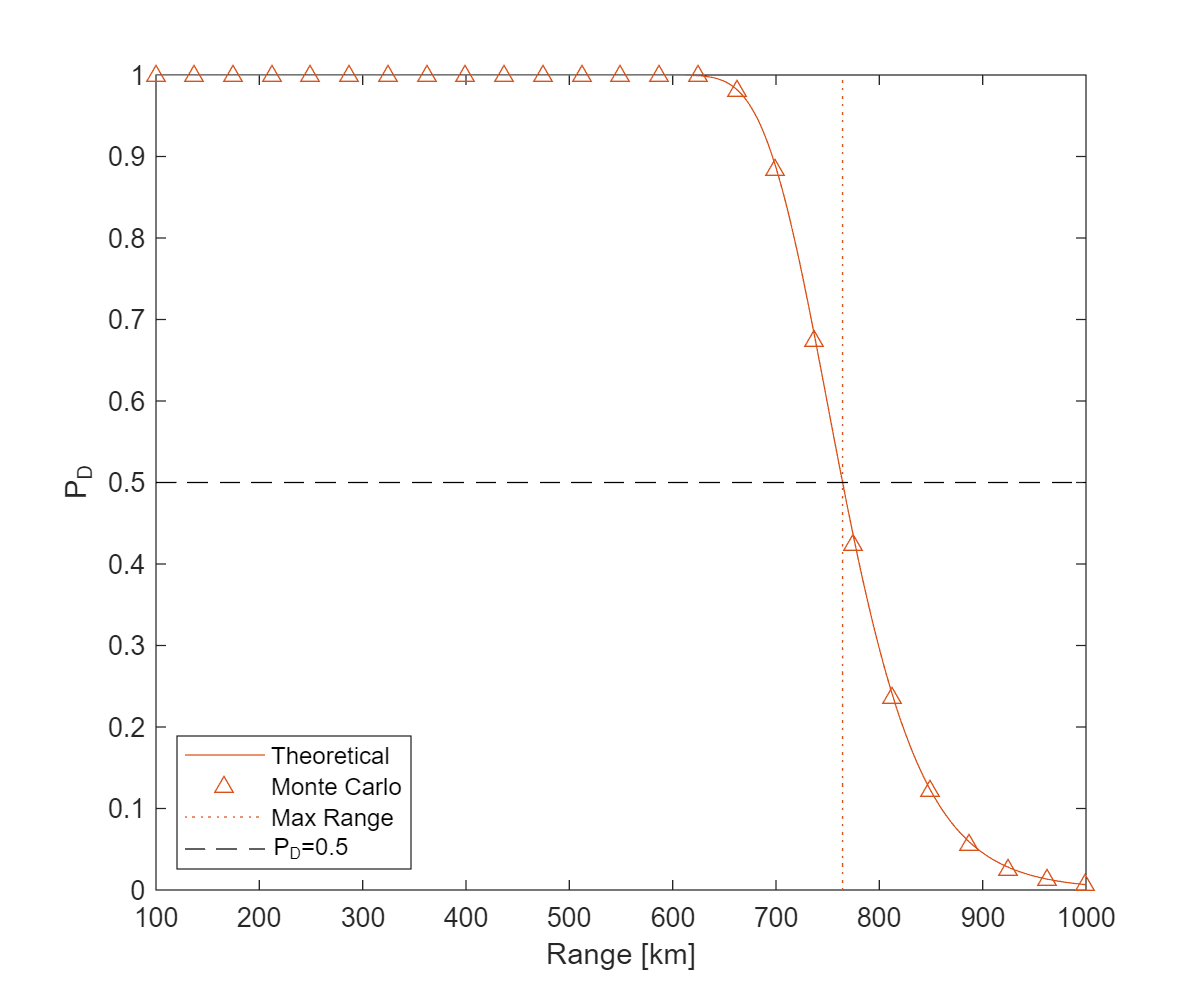

min_range_km = 100; % Min Range
max_range_km =1000;  % Max Range
nMC = 10000;          % Number of Monte Carlo Trials to run

% Check for existence of Statistics & Machine Learning Toolbox
use_stat_toolbox = license('test','Statistics_Toolbox');
   % If TRUE, then built-in functions will be used.
   % If FALSE, then custom-builts replacements in the utils namespace will
   % be used.
   
%  At each range, compute the received
%  power level.  Conduct a monte carlo trial
%  at each power level to compute PD and compare
%  to the desired threshold.

Rvec= linspace(min_range_km,max_range_km,1000)*1e3;         % Fine range samples for plotting a smooth curve
Rvec_coarse = linspace(min_range_km,max_range_km,25)*1e3;   % Coarse range samples for markers

% Compute Path loss at each range
Lprop = prop.pathLoss(Rvec,f0,ht,hr,false);
Lprop_coarse = prop.pathLoss(Rvec_coarse,f0,ht,hr,false);

% Received Power and SNR
Pr = EIRP-Lprop+Gr-Lr;
Pr_coarse = EIRP-Lprop_coarse+Gr-Lr;

% Convert noise and signal power to linear units
Nlin = 10.^(N/10);
Pr_lin = 10.^(Pr_coarse/10);
xi = Pr-N;
xi_lin = 10.^(xi/10);

% Theoretical Result
if use_stat_toolbox
    eta = chi2inv(1-prob_fa,2*M);
    probD_theo = 1-ncx2cdf(eta,2*M,2*M.*xi_lin);
else
    eta = utils.chi2inv(1-prob_fa,2*M);
    probD_theo = 1-utils.ncx2cdf(eta,2*M,2*M.*xi_lin);
end

% Generate noise and signal vectors
n = sqrt(Nlin/2) * (randn(M,nMC) + 1i*randn(M,nMC)); % Complex Gaussian with variance of N
start_phase = 2*pi*rand(1,nMC);
pulse = exp(1i*2*pi*(0:M-1)/10); % Unit Power
s = pulse(:).*exp(1i*start_phase);

% Compute Sufficient Statistic
probD = zeros(size(Pr_coarse));
for rngidx = 1:numel(Pr_coarse)
    % Scale signal power
    thisS = sqrt(Pr_lin(rngidx))*s;

    % Run Energy Detector
    detResult = detector.squareLaw(n+thisS,Nlin/2,prob_fa);
    
    % Count detections
    probD(rngidx) = sum(detResult)/nMC;
end

fig=figure;
colors = get(0,'DefaultAxesColorOrder');
plot(Rvec/1e3,probD_theo,'Color',colors(2,:),'DisplayName','Theoretical');
hold on;
plot(Rvec_coarse/1e3,probD,'^','Color',colors(2,:),'DisplayName','Monte Carlo');
plot(R_soln/1e3*[1 1],[0 1],':','Color',colors(2,:),'DisplayName','Max Range');

plot(Rvec_coarse/1e3,probD_desired*ones(size(Rvec_coarse)),'k--','DisplayName','P_D=0.5');

xlabel('Range [km]');
ylabel('P_D');
ylim([0,1]);
legend('Location','SouthWest');